# Numerical Methods Assignment 1

Group 11

Noah Labuschagne S6621635

Danail Valov S5609895

Bashar Alsayed S4029291

**Instructions:**

- Submit the assignment by the deadline on September 16 at 14:00 via Brightspace. All group members must be enrolled in the group before the assignment is submitted.

- Submit two files: this .mlx file and an .pdf export of the same file. Save both files as NM_AS1_GroupX.mlx and NM_AS1_GroupX.pdf, replacing the X by your group number.

- Ensure your group number, names and student numbers are at the top of the document.

- **Consult the course description for details** on the assignment, including information on the discussion and the generative AI policy.

- Include a statement on the ways in which you used generative AI, if any, in the box below. If you worked individually, ensure every group members writes their own statement.

- This type of MATLAB file is called a Live Code File Format (.mlx). It allows you to have all code in one place, and show code, generated figures, text, and equations all next to eachother. It is fairly self-explanatory, but this page and links within it provide some further explanation: [http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.](http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.) You are welcome to remove the text of the assignment or keep it and add in your solutions. 

## Generative AI statement

#### *Noah Labuschagne (Part 1)*

AI was not used to generate any code. AI was used infrequently for debugging.

#### *Danail Valov (Part 2)*

AI was not used to generate code; it was used to find sources to specific syntax questions I had regarding the software and to check for bugs and typos once the code was already written out.

#### *Bashar Alsayed (Part 3)*

I used AI to help me learn how to write in MATLAB code and syntax since the document provided on Brightspace was not enough for a total beginner like me. I also used it to correct my code if I made mistakes, and used it to correct my grammar because I am bad at spelling. The one thing I refused to do is make AI do all the work for me, or get the assignments done without knowing what is going on or how to write in MATLAB (I still am a beginner, but at least I know something now).

The provided explanation of why I chose what I chose was because I understood that getting the derivative in the problem would take longer. Also, I made a deliberate choice of not choosing the bisection method. It was my own criteria that the iterations must not be more than 10.

## Set-up *(12 pts.)*

This assignment in on the root-finding methods that are discussed in Chapter 4 of the lecture notes. As you will require an implementation for each other the four methods, start by defining these in the next few blocks of code. The first three tutorials provide instructions on how to implement these functions. Use the stopping criteria suggested during lectures. 

Ensure you are calling the functions you define here in Problems 1-3.

### Bisection Method

% Implementation of the bisection method
function [root, rootvec] = bisection_method(f, l, u, maxit)
m = ( l + u ) / 2;
it = 1;
rootvec = zeros(1, maxit);

while it <= maxit 
rootvec(it) = m;
prod = f(l) * f(m);
if prod < 0
u = m ;
else
l = m ;
end
m = ( l + u ) / 2; 
it = it + 1; 
end
root = m;
rootvec = rootvec(rootvec ~= 0)

dexact = rootvec(end);
itvec = 0:(length(rootvec)-1);
errvec = abs(rootvec-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
title('Bisection Method')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on

end

### Fixed-Point Iteration Method

rootvec =     0.5000    0.2500    0.1250    0.0625    0.0312    0.0469    0.0391    0.0352    0.0332    0.0342    0.0337    0.0339    0.0338    0.0338    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337


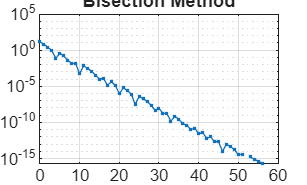

root = 0.0337

% Implementation of fixed-point iteration
function [rootFPI, rootvec_FPI] = fixed_point_iteration(g, x0, maxit, tol)

it = 1;
xk = x0;
xk1 = g(xk);
rootvec_FPI = zeros(1, maxit);
while abs((xk1-xk)/xk1) > tol && it < maxit
    rootvec_FPI(it) = xk;
    xk = xk1;
    xk1 = g(xk);
    it = it+1;
end
rootvec_FPI(it) = xk1;
rootFPI = xk1;
rootvec_FPI = rootvec_FPI(rootvec_FPI ~= 0)

dexact = rootvec_FPI(end);
itvec = 0:(length(rootvec_FPI)-1);
errvec = abs(rootvec_FPI-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
title('Fixed-Point Iteration Method')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

### Newton-Raphson Method

rootvec_FPI = 1.0e+84 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   7.5077 - 0.8115i      Inf +    Infi


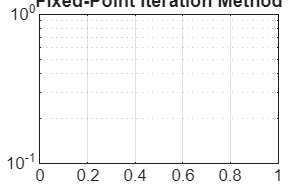

root = Inf +    Infi

% Implementation of Newton-Raphson
function [root_nrm, rootvec_nrm] = newton_raphson_method(f, f_prime, x0, maxit, tol)

rootvec_FPI =     0.0378    0.0327    0.0339    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337


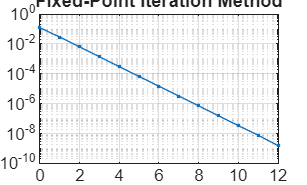

root = 0.0337

xk = x0;

rootvec_nrm =     1.0000    0.6339    0.3931    0.2371    0.1388    0.0801    0.0488    0.0362    0.0338    0.0337    0.0337


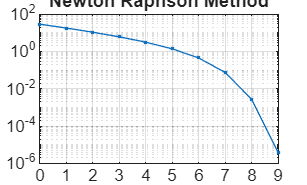

roota = 0.0337

xk1 = xk - (f(xk)/f_prime(xk));
it = 1;
rootvec_nrm = zeros(1, maxit);
while abs((xk1-xk)/xk1) > tol && it < maxit
    rootvec_nrm(it) = xk;
    xk = xk1;
    xk1 = xk - (f(xk)/f_prime(xk));
    it = it + 1;
end
rootvec_nrm(it) = xk1;
root_nrm = xk1;
rootvec_nrm = rootvec_nrm(rootvec_nrm ~= 0)

dexact = rootvec_nrm(end);
itvec = 0:(length(rootvec_nrm)-1);
errvec = abs(rootvec_nrm-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
title('Newton Raphson Method')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

### Secant Method

rootvec_sm =    10.0000   20.0000    8.5421    7.5487    5.2974    4.0725    3.0156    2.2574    1.6743    1.2382    0.9092    0.6623    0.4775    0.3401    0.2388    0.1652    0.1130    0.0772    0.0542    0.0412    0.0355    0.0339    0.0337    0.0337    0.0337


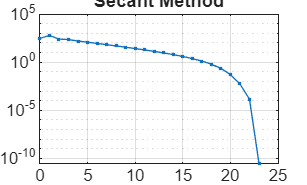

roota = 0.0337

% Implementation of the secant method%
function [root_sm, rootvec_sm]= secant_method(f, x0, x1, maxit, tol)
xk = x0;
xk1 = x1;
var1=f(xk);
var2=f(xk1);
xk2 = xk1 - var2*((xk-xk1)/(var1-var2));
it = 1;
rootvec_sm = zeros(1, maxit+1);

while abs((xk2-xk1)/xk2) > tol && it < maxit
    rootvec_sm(it) = xk;
    xk = xk1;
    xk1 = xk2;
    var1=var2;
    var2=f(xk1);
    xk2 = xk1 - var2*((xk-xk1)/(var1-var2));

rootvec_sm =     1.0000    0.0004    0.0008    0.2152    0.0048    0.0087    0.0757    0.0208    0.0277    0.0353    0.0336    0.0337    0.0337    0.0337


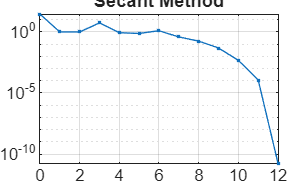

roota = 0.0337

    it = it + 1 ;
end
rootvec_sm(it) = xk1;
rootvec_sm(it+1) = xk2;
root_sm = xk2;

rootvec_sm = rootvec_sm(rootvec_sm ~= 0)

dexact = rootvec_sm(end);
itvec = 0:(length(rootvec_sm)-1);
errvec = abs(rootvec_sm-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
title('Secant Method')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

rootvec =     0.5000    0.2500    0.1250    0.0625    0.0312    0.0469    0.0391    0.0352    0.0371    0.0361    0.0366    0.0364    0.0365    0.0366    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365


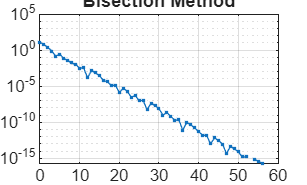

rootb = 0.0365

%Secant Method without plotting

function [root_sm, rootvec_sm]= secant_method_np(f, x0, x1, maxit, tol)
xk = x0;
xk1 = x1;
var1=f(xk);
var2=f(xk1);
xk2 = xk1 - var2*((xk-xk1)/(var1-var2));
it = 1;
rootvec_sm = zeros(1, maxit+1);

while abs((xk2-xk1)/xk2) > tol && it < maxit

rootvec_FPI = 1.0e+84 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   7.5077 - 0.8115i      Inf +    Infi


root = Inf +    Infi

    rootvec_sm(it) = xk;
    xk = xk1;
    xk1 = xk2;
    var1=var2;
    var2=f(xk1);
    xk2 = xk1 - var2*((xk-xk1)/(var1-var2));
    it = it + 1 ;
end
rootvec_sm(it) = xk1;
rootvec_sm(it+1) = xk2;
root_sm = xk2;
rootvec_sm = rootvec_sm(rootvec_sm ~= 0);

dexact = rootvec_sm(end);
itvec = 0:(length(rootvec_sm)-1);

rootvec_FPI =     0.0378    0.0327    0.0339    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337


root = 0.0337

errvec = abs(rootvec_sm-dexact)/abs(dexact);

end

## Problem 1: Pump operating point and energy consumption *(30 pts.)*

### Problem description

A pumping system transports water from a lower reservoir to an upper reservoir located 8 m higher. The reservoirs are connected by a 500 m-long pipe with an internal diameter of 0.15 m. See below a diagram of the situation:

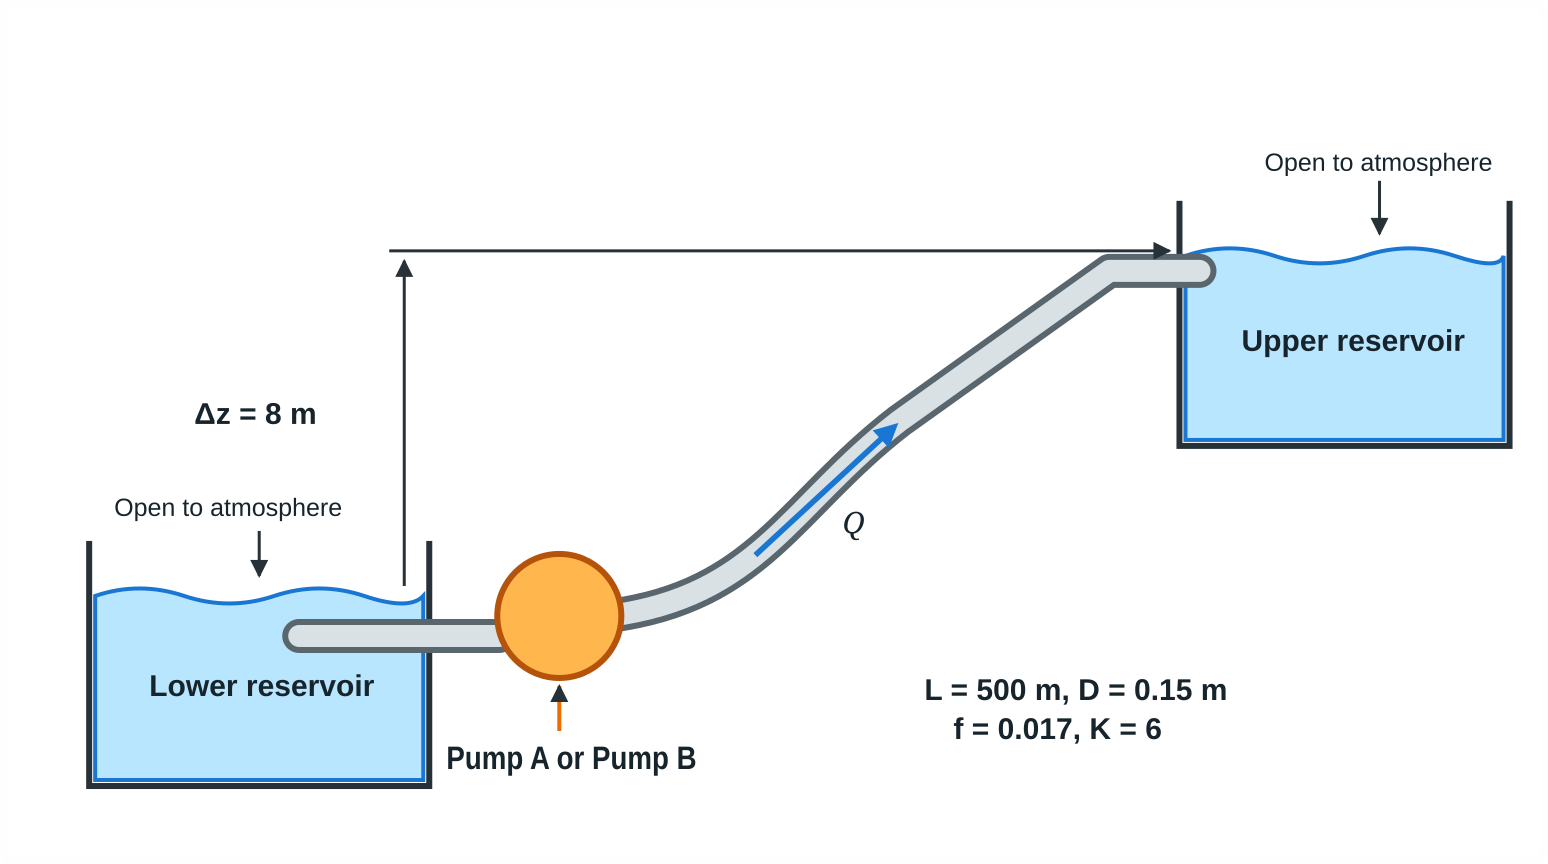

Two pumps are available: pump A and pump B. In this question, you will decide whether you prefer pump A or pump B. We start off by providing all the information necessary for you to answer this question. 

### Pump characteristic curves

The pressure head supplied by each pump $H_{\mathrm{pump}}$ (expressed in m) is represented by the following empirical equation:

$H_{\mathrm{pump}}(Q)
=
H_0-bQ-aQ^2-cQ^3$,

where $Q$ is the volumetric flow rate, expressed in m³/s, $H_0$ is the maximum pressure head produced by the pump when the flow rate is zero. This value is also called the shut-off head. The coefficients $a$, $b$, and $c$ describe how the pump head decreases as the flow rate increases:

• $b$ controls the initial linear decrease in the pump head.

• $a$ represents the quadratic curvature of the pump characteristic curve.

• $c$ captures the stronger nonlinear reduction in pump head at high flow rates.

These coefficients are generally obtained by fitting the polynomial model to experimental pump-performance data supplied by the manufacturer. The supplier has subplied the following parameters.

#### Pump parameters

### System curve

The pressure head required by the piping system $H_{\mathrm{system}}$ (expressed in m) is given by

$H_{\mathrm{system}}(Q)
=
\Delta z
+
\left(
f\frac{L}{D}+K
\right)
\frac{v(Q)^2}{2g}$,

where $Q$ is again the flow rate. The mean velocity $v(Q)$ is related to the flow rate $Q$ according to the equation


$$v(Q)=\frac{Q}{A},$$


where $A$ is the cross-sectional area of the pipe. The system described use the following system parameters

Assume that the friction factor remains constant over the operating range. 

### Operating point

The operating point $Q^*$ occurs when the pressure head supplied by the pump is equal to the pressure head required by the piping system:


$$H_{\mathrm{pump}}(Q^*)=H_{\mathrm{system}}(Q^*)$$


Because the pressure head supplied by a pump depends on the flow rate, the operating flow rate is not known in advance.

### Energy-consumption analysis

We can calculate the electrical energy consumed during one hour of continuous operation of a pump.

#### Hydraulic power

The hydraulic power (in kilowatts) transferred from the pump to the water is

$P_{\mathrm{hydraulic}}
=
\frac{\rho gQH}{1000}$,

where:

- $Q$ is the operating flow rate in m³/s.

- $H$ is the head at the operating point in m.

- $P_{hydraulic}$ is the hydraulic power in kW.

- $\rho$ is the water density, use $\rho=998\,\mathrm{kg/m^3}$.

#### Electrical power

The electrical power required by the pump is

$P_{\mathrm{electrical}}
=
\frac{P_{\mathrm{hydraulic}}}{\eta}$,

where $\eta$ is the efficiency of the pump.

#### Electrical energy consumed per hour

Electrical energy is calculated as

$E=P_{\mathrm{electrical}} \cdot  t$.

When the electrical power is expressed in kW and the operating time is expressed in hours, the resulting electrical energy is expressed in kWh.

## Problem 1: 

Considering the information above and the problem description,

    a. Compute the operation point for both pumps. Use all four numerical methods for root-finding discussed and generate convergence plots. Explain what choices you made for each method and motivate them. Clearly explain the pros and cons of each method, based on the observed behaviour, and motivate a decision for the best numerical method. *(****15 pts.****)*

    b. Choose one of the pumps based on its power consumption and the volume it can transport. *(****5 pts.****)*

Note: All of your calculations and reasoning must be clearly explained as text, in order to receive full marks. 

# Solutions problems 1a and 1b

## ***Part a***

***General Parameters***

Here I defined the general paramters that are used for both pumps.

L = 500; % Pipe length (m)
D = 0.15; % Pipe diameter (m)
dz = 8; % Elevation difference (m)
fr = 0.017; % Darcy friction factor
K = 6; % Minor-loss convergence
g = 9.81; % Gravitational acceleration (ms^-2)
A = (D/2)^2 * pi;
rho = 998; %Water density (kgm^-3)
t = 1; %Time (hours)
mu = 10e-3; %Dynamic viscosity of water (kg/(ms)^-1)

***Pump A Parameters***

Here I defined the parameters that are specific to Pump A.

rootvec_nrm =     1.0000    0.7198    0.5014    0.3342    0.2104    0.1239    0.0698    0.0431    0.0364    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365    0.0365


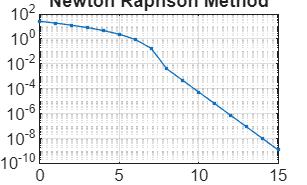

rootb = 0.0365

H0a = 34; % Maximum pressure head produced when flow rate is 0
ba = 100; % Linear pump head coefficient
aa = 8000; % Quadratic pump head coeffcient
ca = 5E+4; % Stronger nonlinear pump head coefficient
na = 0.7; % Efficiency

ka = 4.5e-5; % Roughness

**Pump A Bisection Method**

V = @(Q) Q/A;
Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0a - ba*Q - aa*(Q.^2) - ca * (Q.^3);


f = @(Q) Hs(Q) - Hp(Q);

maxit = 100;

tol = 10e-10;

%root = bisection_method(f, -1000,1000 , maxit) %First try with initial values

root = bisection_method(f, 0,1, maxit) %Second try with much closer initial values


Here the bisection method was implemented to find the root of the equation. The first try was with very spread apart intial values. The second was with much closer initial values. Easy to find the root if it is within your intial values but not the quickest method, relative error decreases linearly.

**Pump A Fixed Point Iteration**

rootvec_sm =     1.0000    0.0006    0.0013    0.2757    0.0053    0.0091    0.0869    0.0218    0.0295    0.0385    0.0363    0.0365    0.0365    0.0365


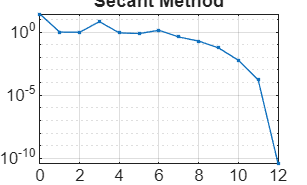

rootb = 0.0365

V = @(Q) Q/A;

Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0a - ba*Q - aa*(Q.^2) - ca * (Q.^3);


g1 = @(Q) Hs(Q) - Hp(Q) + Q;
g2 = @(Q) sqrt((Hp(Q) - dz) * 2*g*A^2/(fr*L/D + K));
g3 = @(Q) (H0a - dz - ((fr*L/D + K)/(2*g*A^2) + aa)*Q.^2 - ca*Q.^3)/ba;
g4 = @(Q) sqrt(((H0a - dz) - ba*Q - ca*Q.^3)/((fr*L/D + K)/(2*g*A^2) + aa));

Phydroa = 6.4762


maxit = 1000000;

Peleca = 9.2517


tol = 10e-10;

E = 9.2517


%root = fixed_point_iteration(g1, 1 , maxit, tol) %First try with g1 

Eff = 70

%root = fixed_point_iteration(g1, 0, maxit, tol) %First try with g1 from the other side 


70.0000000000000000


%root = fixed_point_iteration(g2, 1, maxit, tol) %Let's try with g2
%root = fixed_point_iteration(g2, 1, maxit, tol) %Let's try from the other side

Phydrob = 7.7302


%root = fixed_point_iteration(g3, 1, maxit, tol) %Let's try with g3

Pelecb = 9.4271

%root = fixed_point_iteration(g3, 1, maxit, tol) %Let's try from the other side

root = fixed_point_iteration(g4, 1, maxit, tol) %Let's try with g4

E = 9.4271

root = fixed_point_iteration(g4, 0, maxit, tol) %Let's try from the other side


Eff = 82

I tried with various equations for g. The first one(g1) was the easiest and most obvious but did not work from either sides. I then isolated Q in various ways with g2, g3, and g4. Only g4 converged and only when the initial guess was 0. The relative error decreased linearly and in much fewer iterations than with the bisection method. Fast but can be tricky to find working equations for g and good itial guesses.

**Pump A Netwton-Raphson**

V = @(Q) Q/A;

82.0000000000000000


Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0a - ba*Q - aa*(Q.^2) - ca * (Q.^3);


f = @(Q) Hs(Q) - Hp(Q);

f_prime = @(Q) ((fr*L/D) + K) * Q / (g * A^2) + ba + 2 * aa * Q + 3 * ca * Q.^2;

maxit = 1000000;

%x0 = 10;

x0 = 1;

tol = 10e-10;

roota = newton_raphson_method(f, f_prime, x0, maxit, tol)

I found the derivative f_prime and used it. The relative error decreased quadratically. Very fast but you need to be able to find the first derivative of f. Tried with x0 = 10 first and then with x0 = 1. Half as many iterations needed with x0 = 1. Initial guess is important.

**Pump A Secant Method**

V = @(Q) Q/A;
Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0a - ba*Q - aa*(Q.^2) - ca * (Q.^3);


f = @(Q) Hs(Q) - Hp(Q);


maxit = 1000000;

x0 = 10;
x1 = 20;

tol = 10e-10;

roota = secant_method(f, x0, x1, maxit, tol)

x0 = 0;
x1 = 1;

roota = secant_method(f, x0, x1, maxit, tol)


Relative error decreases super linearly. Fast but not as fast as Newton Raphson and needs good values for x0 and x1. Initially I used 10 and 20 for x0 and x1 respectively. Then 0 and 1 were used. 

### **Pump B**

**Pump B Parameters**

H0b = 42; % Maximum pressure head produced when flow rate is 0
bb = 80; % Linear pump head coefficient
ab = 12e+3; % Quadratic pump head coeffcient
cb = 3e+4; % Stronger nonlinear pump head coefficient
nb = 0.82; % Efficiency
kb = 3e-5; % Roughness

**Pump B Bisection Method **

V = @(Q) Q/A;
Hs = @(Q) dz + (fr*L/D + K) * ((V(Q)).^2/(2*g));
Hp = @(Q) H0b - bb*Q - ab*(Q.^2) - cb * (Q.^3);


f = @(Q) Hs(Q) - Hp(Q);

maxit = 1000000;

tol = 10e-10;


Unrecognized function or variable 'Rea'.

Error in NM_IEM_AS1>@(fr,ReC)-2*log10(ka/(3.7*D)+2.51/(Rea*sqrt(fr)))-1/sqrt(fr) (line 334)
Cf = @(fr, ReC) -2*log10(ka/(3.7*D) + 2.51/(Rea * sqrt(fr))) - 1/sqrt(fr);
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in NM_IEM_AS1>@(f)Cf(f,ReC) (

rootb = bisection_method(f, 0, 1 , maxit)

Here the bisection method was implemented to find the root of the equation. I tried with the same intial values used for Pump A since I expected the root to be similar. Easy to find the root if it is within your intial values but not the quickest method, relative error decreases linearly.

**Pump B Fixed Point Iteration**

V = @(Q) Q/A;
Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0b - bb*Q - ab*(Q.^2) - cb * (Q.^3);


g4 = @(Q) sqrt(((H0a - dz) - ba*Q - ca*Q.^3)/((fr*L/D + K)/(2*g*A^2) + aa));

maxit = 1000000;

tol = 10e-10;


root = fixed_point_iteration(g4, 1, maxit, tol) %Let's try with g4
root = fixed_point_iteration(g4, 0, maxit, tol) %Let's try from the other side

I already had a working equation for g (g4) from Pump A so I used that to find the root for Pump B. Similarly to Pump A it only converges when the initial guess is 0 and diverges when the initial guess is 1. Relative error decreases linearly. Fast but can be tricky to find working equations for g and good itial guesses.

**Pump B Newton-Raphson **

V = @(Q) Q/A;
Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0b - bb*Q - ab*(Q.^2) - cb * (Q.^3);


f = @(Q) Hs(Q) - Hp(Q);

f_prime = @(Q) ((fr*L/D) + K) * Q / (g * A^2) + ba + 2 * aa * Q + 3 * ca * Q.^2;

maxit = 1000000;

x0 = 1;

tol = 10e-10;

rootb = newton_raphson_method(f, f_prime, x0, maxit, tol)

The relative error decreased quadratically. Very fast but you need to be able to find the first derivative of f and a good x0 impacts the speed greatly. Used the same x0 of 1 as I used for Pump A. 

**Pump B Secant Method**

V = @(Q) Q/A;
Hs = @(Q) dz + ((fr*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0b - bb*Q - ab*(Q.^2) - cb * (Q.^3);


f = @(Q) Hs(Q) - Hp(Q);


maxit = 1000000;

x0 = 0;
x1 = 1;

tol = 10e-10;

rootb = secant_method(f, x0, x1, maxit, tol)

Relative error decreases super linearly. I used the same x0 and x1 as used for Pump A.  Fast but not as fast as Newton Raphson and good x0 and x1 are needed.

Overall I think that the best method for this prohblem is the Newton Raphson method because it is the fastest and doesn't rely heavily on good initial guesses. However, it only works if the first derivative of f can be found. 

## **Part 1b**

### **Power Consumption**

#### **Pump A**

Phydroa = (rho * g * roota * Hs(roota))/1000 %Using the given formula to find the hydraulic power

Peleca = Phydroa/na %Using the given formula to find the electrical power

E = Peleca * t % Converting to kWh

Eff = Phydroa/Peleca * 100 %Finding the efficiency 

fprintf('%.16f\n',Eff);

#### **Pump B**

Phydrob = (rho * g * rootb * Hs(rootb))/1000 %Using the given formula to find the hydraulic power

Pelecb = Phydrob/nb %Using the given formula to find the electrical power


E = Pelecb * t % Converting to kWh

Eff = Phydrob/Pelecb * 100 %Finding the efficiency

fprintf('%.16f\n',Eff)

Since both pumps have the same efficiency the choice of pump depends on the volume of water needed to be tranpsorted. Pump A can transport less water but also uses less electricity so should be used if pumps are on constantly and power usage should be minimised. Pump B can transort more water but used more electricity so should be used if volume of water transported should be maximised. 

## **Problem 1c: challenging extension on **flow-dependent friction factor **(**10 points)

In Problem 1a-b, the friction factor was assumed to be constant, $$f=0.017$
$. A more realistic model calculates $$f$$ using the Colebrook equation when the flow is turbulent, as we have seen in the lectures. The internal roughness of the pipes are slightly different. The roughness of pump A is $k_A = 4.5\times10^{-5}$ m and of pump B $k_B = 3\times10^{-5}$ m. Use for the dynamic viscocity of water $\mu = 10^{-3}$ kg/(ms).

Note that the Colebrook equation is only valid for flows with Reynolds number greater than 4000. For all smaller Reynolds numbers, extend the laminar friction factor equation:


$$f = \frac{64}{Re}.$$


Determine a new operating point and choose the pipe with the lowest energy consumption. You need not compare all numerical methods, but ensure that you motivate the choices that you made. Clearly explain your full approach.

# Solution problem 1c

*Add your solution here using written text, equations, and blocks of code.*

#### *Pump A*


%Equations
V = @(Q) Q/A;

Re = @(Q) (rho * V(Q) * D)/mu;

Cf = @(fr, ReC) -2*log10(ka/(3.7*D) + 2.51/(Rea * sqrt(fr))) - 1/sqrt(fr);


%Function for different Reynolds numbers
    
function fr = Cfra(Q, V, Re, Cf, maxit, tol)
    ReC = Re(Q);
    if ReC > 4000
        fr = secant_method_np(@(f) Cf(f, ReC), 0.01, 0.05, maxit, tol);
    else
        fr = 64 / ReC;
    end
end


Here we right a function that solves the colebrook equation using the secant method if the Reynolds number is greater than 4000. I used the secant method because it is the fastest if the derivative of f is not available. A new secant method (secant_method_np) was used since we don't want it to plot the relative error.

%Solving


frS = @(Q) Cfra(Q, V, Re, Cf, maxit, tol);


Hs = @(Q) dz + ((frS(Q)*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0a - ba*Q - aa*(Q.^2) - ca * (Q.^3);

f = @(Q) Hs(Q) - Hp(Q);




maxit = 100;

tol = 10e-14;


rootroota = bisection_method(f, 0, 1, maxit)

The functions were then called and the equation was solved using bisection method since it is the easiest to use. Our computing cost is not high therefore the amount of iterations needed is to reach an appropraite root is not very important. If our computing cost would be very high then a faster method should be used.

#### *Operating Point A*

Phydroa = (rho * g * roota * Hs(roota))/1000 %Finding the hydraulic power using the given equation.


Peleca = Phydroa/na %Finding the electical power using the given equation.

E = Peleca * t %Converting to kWh

Eff = Phydroa/Peleca * 100 %Finding the efficiency

fprintf('%.16f\n',Eff);

#### *Pump B*

%Equations
V = @(Q) Q/A;

Re = @(Q) (rho * V(Q) * D)/mu;

Cf = @(fr, ReC) -2*log10(kb/(3.7*D) + 2.51/(Rea * sqrt(fr))) - 1/sqrt(fr);


%Function for different Reynolds numbers
    
function fr = Cfrb(Q, V, Re, Cf, maxit, tol)
    ReC = Re(Q);
    if ReC > 4000
        fr = secant_method_np(@(f) Cf(f, ReC), 0.01, 0.05, maxit, tol);
    else
        fr = 64 / ReC;
    end
end


Here we right a function that solves the colebrook equation using the secant method if the Reynolds number is greater than 4000. I used the secant method because it is the fastest if the derivative of f is not available. A new secant method (secant_method_np) was used since we don't want it to plot the relative error.

%Solving


frS = @(Q) Cfrb(Q, V, Re, Cf, maxit, tol);


Hs = @(Q) dz + ((frS(Q)*L/D) + K) * ((V(Q)).^2/(2 * g));
Hp = @(Q) H0b - bb*Q - ab*(Q.^2) - cb * (Q.^3);

f = @(Q) Hs(Q) - Hp(Q);




maxit = 100;

tol = 10e-14;


rootrootb = bisection_method(f, 0, 1, maxit)

The functions were then called and the equation was solved using bisection method since it is the easiest to use. Our computing cost is not high therefore the amount of iterations needed is to reach an appropraite root is not very important. If our computing cost would be very high then a faster method should be used.

#### *Operating Point B*

Phydrob = (rho * g * rootb * Hs(rootb))/1000 %Finding the hydraulic power using the given equation.

Pelecb = Phydrob/nb %Finding the electical power using the given equation.

E = Pelecb * t %Converting to kWh

Eff = Phydrob/Pelecb * 100 %Finding the efficiency

fprintf('%.16f\n',Eff);

I would now choose Pump B since it can transport more water and has a higher efficiency.

## Problem 2: Cantilever Beam *(26 pts.)*

#### Problem description

A machine with a weight of $$$P=10\ \mathrm{kN}$ must be installed on a cantilever beam. The beam is fixed at its left end and has a total length of $L=2.0\ \mathrm{m}$. The machine is modeled as a concentrated vertical load acting at a distance $x$ from the fixed support.
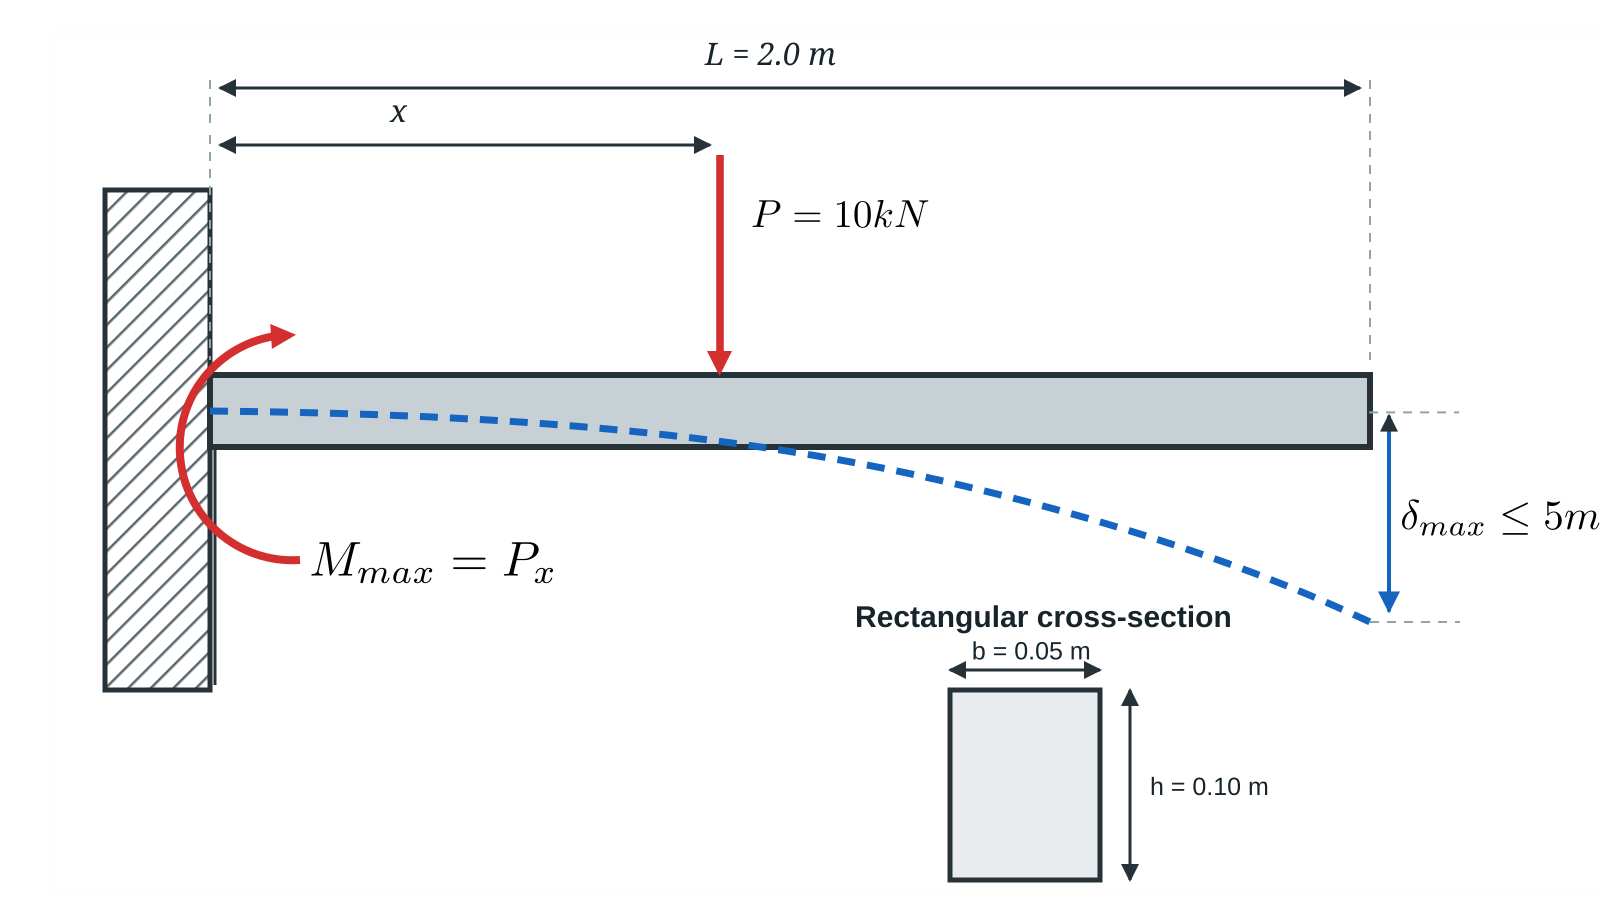
The position of the machine must satisfy three design requirements:

- The maximum bending stress at the fixed support must not exceed the allowable stress of the material.

- The maximum vertical deflection of the beam must not exceed the allowable deflection.

- The load position must, naturally, satisfy: 


$$$$
0\leq x\leq L.
$$$$


We provide further information on the properties of the beam and how to calculate maximum bending stress and maximum vertical deflection below. The questions of the problem are stated after that.


### Beam and material properties

The beam is made of steel and has a rectangular cross-section. Use the following properties:


### Cross-section properties

For a rectangular cross-section, the second moment of area about the neutral axis is


$$$$
I=\frac{bh^3}{12}
$$$$


The distance from the neutral axis to the outermost fibre is


$$$$
c=\frac{h}{2}
$$$$


### Stress constraint

For a concentrated load $$P$$ applied at a distance $$x$$ from the fixed support, the maximum bending moment occurs at the fixed support:

$$$
M_{\max}=Px
$$$.

The corresponding maximum bending stress is

$$$
\sigma_{\max}(x)
=
\frac{M_{\max}c}{I}
$$$.

The beam satisfies the stress requirement when


$$$$
\sigma_{\max}(x)
\leq
\sigma_{\mathrm{allow}}
$$$$


The maximum allowable position according to the stress constraint is denoted by $$$
x_{\max}
$$
$.

### Deflection constraint

The load is not necessarily applied at the free end of the beam. The beam continues from the load position $$x$
$ to the free end at $$L$$.

The vertical deflection at the load position is


$$$$
\delta_P(x)
=
\frac{Px^3}{3EI}
$$
$$


The free-end deflection is


$$$$
\delta_{\mathrm{tip}}(x)
=
\frac{Px^2(3L-x)}{6EI}

$$
$$


The beam satisfies the deflection requirement when

$$$
\delta_{\mathrm{max}}(x)
\leq
\delta_{\mathrm{allow}}
$$
$,

where $\delta_{\max}$ is the maximum deflection, which happens either at the load position or at the free-end.

### Safety factor


Define the safety factor against bending as


$$$$n=\frac{\sigma_{\mathrm{allow}}}{\sigma_{\max}}$$$$


### Problem 2: 

Complete the following tasks:

**a**. Determine the maximum distance $$x_{\max}$$ from the fixed support at which the force can be applied while satisfying all design requirements. Use root-finding methods and explain which method performs best. As before, explain in detail how the methods were used and generate convergence plots. Describe pros and cons of each method to motivate the best choice. ***(16 pts.)***

**b. **Identify which design requirement governs the maximum allowable position: beam length, allowable bending stress, or allowable deflection. Explain the physical meaning of the governing requirement. ***(5 pts.)***

**c. **Once you have identified the maximum position of the load, determine the safety factor. If it is less than 2, identify which cross-sectional area (width or height) should be modified and what its value should be to meet this requirement. ***(5 pts.)***

# Solution problem 2

#### Problem 2.a)

All four root finding methods were applied to determine the maximum distance (x) for which the effects of the load fall within acceptable thresholds with an engineering factor n >= 1 , and a total deflection d <= 5 mm.

The bisection method has particular advantages compared to the remaining methods since the point x falls between 0 and the total length of the beam (or the domain (0,2)); the problem itself provides the boundary conditions as well as the starting guesses. 

Additionally, the bisection method is also advantaged compared to the other methods since the next guess is not directly governed by the governing equations of the three specific criterions (stress, deflection at point, deflection at tip), but instead by the initial domain and whether the point of evaluation accounts for all three criteria which allows the method to evaluate all three crierions in conjunction with one another rather than seperately.

Unlike the bisection method, the next guesses of the remaining algorithms directly depend on the governing equations of the specific criterion which is being evaluated thereby necesitating three seperate instances of each function to be run in order to evaluate each of the criterions. After each of the criterions is evaluated, the smallest root is selected in order to meet all of the functional requirements. 

In addition, for these remaining algorithms, the rate of convergence as well as whether convergence occurs directly depends on the initial guesses which creates an inconsistent rate of convergence as well as inconsistent results.

While these methods may lead to higher rates of convergence under optimal conditions (good initial guesses), the necessity to call each function three times, and their dependance on the initial guesses creates a possiblity for higher computational costs.

On the other hand, despite its linear rate of convergence, the consistency of the bisection method, and its ability to evaluate all three criterions in conjunction with one another make it a particullary atractive method for this specific problem.

Due to the nature of the problem, a unique version of the bisection method was specifically designed to account for both the stress and deflection values and generate convergence plots for the point (x), the engineering factor (n), and the deflection value (d) from their corresponding arrays.

The remaining methods simply call the available functions which are attatched at the beginning of the document on three seperate instances and select the smallest root in order to account for all three criterions.

In essence, in addition to evaluating all of the relevant constraints in conjunction with one another, the bisection method is capable of delivering consistent results which makes it the best solution to this specific problem.

### Bisection Method

% For reference, all lengths are in meters, the force is in kN, and the 
% values for the maximum stress and elastic modulus have been scaled down 
% by a factor of 1000 in order to maintain SI unit consistency throughout the program.

function [a, xvec, nvec, dvec] = assignment1_prob2 (h, n_goal)
it = 1;
maxit = 20;
xvec = zeros(1, maxit);
nvec = zeros(1, maxit);
dvec = zeros(1, maxit);
tol = 0.0001;

L = 2;
l = 0;
u = L;
P = 10;
b = 0.05;
c = h/2;
I = (b*h^3)/12;
E = 200e9/1000;
stress_allowed = 150e6/1000;
deflection_max = 0.005;

while (u-l) > tol
    x = (l+u)/2;
    stress_actual = (P*x*c)/I;
    n = stress_allowed/stress_actual;

    deflection_at_point = (P*x^3)/(3*E*I);
    deflection_at_tip = (P*x^2*(3*L-x))/(6*E*I);
    deflection_max_actual = max(deflection_at_point, deflection_at_tip);

    if n >= n_goal && deflection_max_actual <= deflection_max
        l = x;    % stress and deflection at x are acceptable
    else
        u = x;    % stress and deflection at x are not acceptable
    end
    
    xvec(it) = x;
    nvec(it) = n;
    dvec(it) = deflection_max_actual;
    it = it + 1;
end

a = [x, n, deflection_max_actual];
xvec = xvec(xvec ~= 0)
nvec = nvec(nvec ~= 0)
dvec = dvec(dvec ~= 0)
 

xexact = xvec(end);
itvec = 0:(length(xvec)-1);
errvec = abs(xvec-xexact)/abs(xexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on

nexact = nvec(end);
itvec = 0:(length(nvec)-1);
errvec = abs(nvec-nexact)/abs(nexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |n_{k}-n^*|/|n^*|')
grid on


dexact = dvec(end);
itvec = 0:(length(dvec)-1);
errvec = abs(dvec-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |d_{k}-d^*|/|d^*|')
grid on

end

assignment1_prob2(0.1, 1)

### Fixed-Point Iteration Method

tol = 0.0001;
maxit = 20;
x0 = 0.1;
P = 10;
h = 0.1;
b = 0.05;
c = h/2;
L = 2;
I = (b*h^3)/12;
E = 200e9/1000;
stress_allowed = 150e6/1000;
deflection_max = 0.005;

stress_max = @(x) I*stress_allowed/(P*c);
deflection_at_point = @(x) (3*E*I*deflection_max)^(1/3);
deflection_at_tip = @(x) ((6*E*I*deflection_max)/(P*(3*L-x)))^(1/2);

a = [0, 0, 0];

a(1) = fixed_point_iteration(stress_max, x0, maxit, tol);

a(2) = fixed_point_iteration(deflection_at_point, x0, maxit, tol);

a(3) = fixed_point_iteration(deflection_at_tip, x0, maxit, tol);

x = min(a)

The fixed-point iteration method has the highest rate of convergence of all of the evaluated root finding algorithms; however, the formulas were also the hardest to derive. 

In terms of convergence rate, the method was the most effective solution for the problem, but it also necesitated the most computational work outside of running the program itself making it the least convenient root finding algorithm to implement.

### Newthon-Raphson Method

tol = 0.0001;
maxit = 20;
x0 = 0.1;
P = 10;
h = 0.1;
b = 0.05;
c = h/2;
L = 2;
I = (b*h^3)/12;
E = 200e9/1000;
stress_allowed = 150e6/1000;
deflection_max = 0.005;

stress_max = @(x) (P*x*c)/I - stress_allowed;
stress_max_derivative = @(x) (P*c)/I;

deflection_at_point = @(x) (P*x^3)/(3*E*I) - deflection_max;
deflection_at_point_derivative = @(x) (P*x^2)/(E*I); 

deflection_at_tip = @(x) ((P*x^2)*(3*L-x))/(6*E*I) - deflection_max;
deflection_at_tip_derivative = @(x) (P*x*(2*L-x))/(2*E*I);



a = [0, 0, 0];

a(1) = newton_raphson_method(stress_max, stress_max_derivative, x0, maxit, tol);

a(2) = newton_raphson_method(deflection_at_point, deflection_at_point_derivative, x0, maxit, tol);

a(3) = newton_raphson_method(deflection_at_tip, deflection_at_tip_derivative, x0, maxit, tol);

x = min(a)

The newton-raphson method was the least effective root finding algorithm for this problem despite it having a quadratic rate of convergence. In addition to necesitating the derivation of the derivatives of each of the functions, it also required the highest number of iterations (19) to determine all three roots with an initial guess of 0.1 on top of the known limitation of the newton-raphson method which necesitates it to make two function evaluations per iteration.

### Secant Method

tol = 0.0001;
maxit = 20;
x0 = 0;
x1 = 0.1;
P = 10;
h = 0.1;
b = 0.05;
c = h/2;
L = 2;
I = (b*h^3)/12;
E = 200e9/1000;
stress_allowed = 150e6/1000;
deflection_max = 0.005;

stress_max = @(x) (P*x*c)/I - stress_allowed;
deflection_at_point = @(x) (P*x^3)/(3*E*I) - deflection_max;
deflection_at_tip = @(x) ((P*x^2)*(3*L-x))/(6*E*I) - deflection_max;

a = [0, 0, 0];

a(1) = secant_method(stress_max, x0, x1, maxit, tol);

a(2) = secant_method(deflection_at_point, x0, x1, maxit, tol);

a(3) = secant_method(deflection_at_tip, x0, x1, maxit, tol);

x = min(a)

Athough the secant function converges superlinearly and can be faster than the linear convergence of the bisection method, the necesity to call the function on three seperate ocassions and select the smallest distance value is inherently less convenient than evaluating the problem relative to all of its constraints symultaneously. Additionally, with a different initial guess, faster convergence is not guaranteed. 

For example, when evaluating the problem with an inital x1 guess of 0.5, the total number of iterations is 14, which is exactly equal to the number of iterations of the bisection method; however, with an initial x1 guess of 0.1, the deflection at the point x never converges and creates absurd guesses for all 20 of its iterations and was only stopped by the maximum iteration criterione which was included in the secant function itself. While this was not problematic in this instance, since deflection of the tip was able to converge to the correct value, if this issue had occured with the formula for the deflection at the tip instead, the true root to the problem would not have been found and the outputted root would not have accounted for the design criterions.

#### Problem 2.b) 

The limiting design criteria is the maximum deflection at the tip of the beam. The load acting on the beam at point x displaces the beam from its starting neutral axis. Due to the geometry and arrangement of the beam and the point at which it is supported, the maximum deflection is always experienced at its tip. At the final point of evaluation, this deflection is approximately equal to the selected maximum deflection value.

#### Problem 2.c) 

Due to the properties of the area moment of inertia (I), the higher said value is, the lower the corresponding stress and deflection become.

By evaluating its governing equation I = (b*h^3)/12, we can clearly see that an increase in the value of the height of the beam is significantly more capable at reducing the stress and deflection experienced by the beam than an identical modification to its width (b), even when the neutral axis (c = h/2) which located in the numerator of the stress calculation is put into consideration. This is due to the fact that the height value still has a higher exponent than its width counterpart even after the neutral axis term reduces the exponent of the height term by 1 (when simplifying and cancelling terms within the expression; this is shown in more detail below).

The outputted x value of the function used for problem 2.a) is taken and used to calculate an approximate solution to the required additional height of the beam in order to satisfy the condition n >= 2 at the specified point. Since the condition for the maximum deflection is already satisfied, and the only term which needs to be modified is the height of the beam, we can find the solution by isolating the height from the other terms relative to the stress acting on the beam.

In order to solve for the height of the beam, we must firstly expand stress_actual into its full form: 

% stress_actual = ((P*x*(h/2))/((b*h^3)/12)).

Afterwards, we can simplify this expression to:

% stress_actual = 6*(P*x)/(b*h^2)

Now that we have a expanded and simplified expression for the stress experienced by the beam, we can set:

% stress_allowed/(6*(P*x)/(b*h^2)) = 2

Afterwards, both sides are multiplied by the numerator on the left to produce:

% stress_allowed = 12*(P*x)/(b*h^2).

Finally, both sides are multiplied by h^2, divided by stress_allowed, and then the square root of both sides is taken, isolating the expression which satisfies the safety factor condition in terms of h:

% h_new = sqrt((12*P*a(1)/(b*stress_allowed)))

Now that we have obtained a value for h which satisfies our engineering safety factor we can also determine the cross-sectional area of the beam and compare it to its original cross-sectional area:

% old_area = h*b
% new_area = h_new*b
% percent_increase_in_area = 1 - new_area/old_area

Finally, we can confirm whether this new height satisfies both the deflection and engineering safety factors by running the function applied in 2.a) again with the new height and n = 2.

% 2.c)
P = 10;
x = 0.6859;
b = 0.05;
h = 0.1;
stress_allowed = 150e6/1000;
h_new = sqrt((12*P*x/(b*stress_allowed)))

old_area = h*b
new_area = h_new*b
percent_increase_in_area = 100 * ((new_area-old_area)/old_area)

assignment1_prob2(h_new, 2)

This second function call confirms that with the modifications that have been made to the height of the beam, the point at which n = 2 is the exact same point (x) which was solved for on the first calling of the function with the original height and n = 1.

## Problem 3: Outlet Temperatures of a Counter-Flow Heat Exchanger (logarithmic mean temperature difference -LMTD) ***(22 pts.)***

## Problem description

A counter-flow heat exchanger is used to heat water using hot oil. The two fluids flow in opposite directions and do not mix (see [https://www.youtube.com/watch?v=NvkZaWLe0Sk](https://www.youtube.com/watch?v=NvkZaWLe0Sk) for an explanation of the device). A simple counter-flow heat exchanger is shown in the below figure:

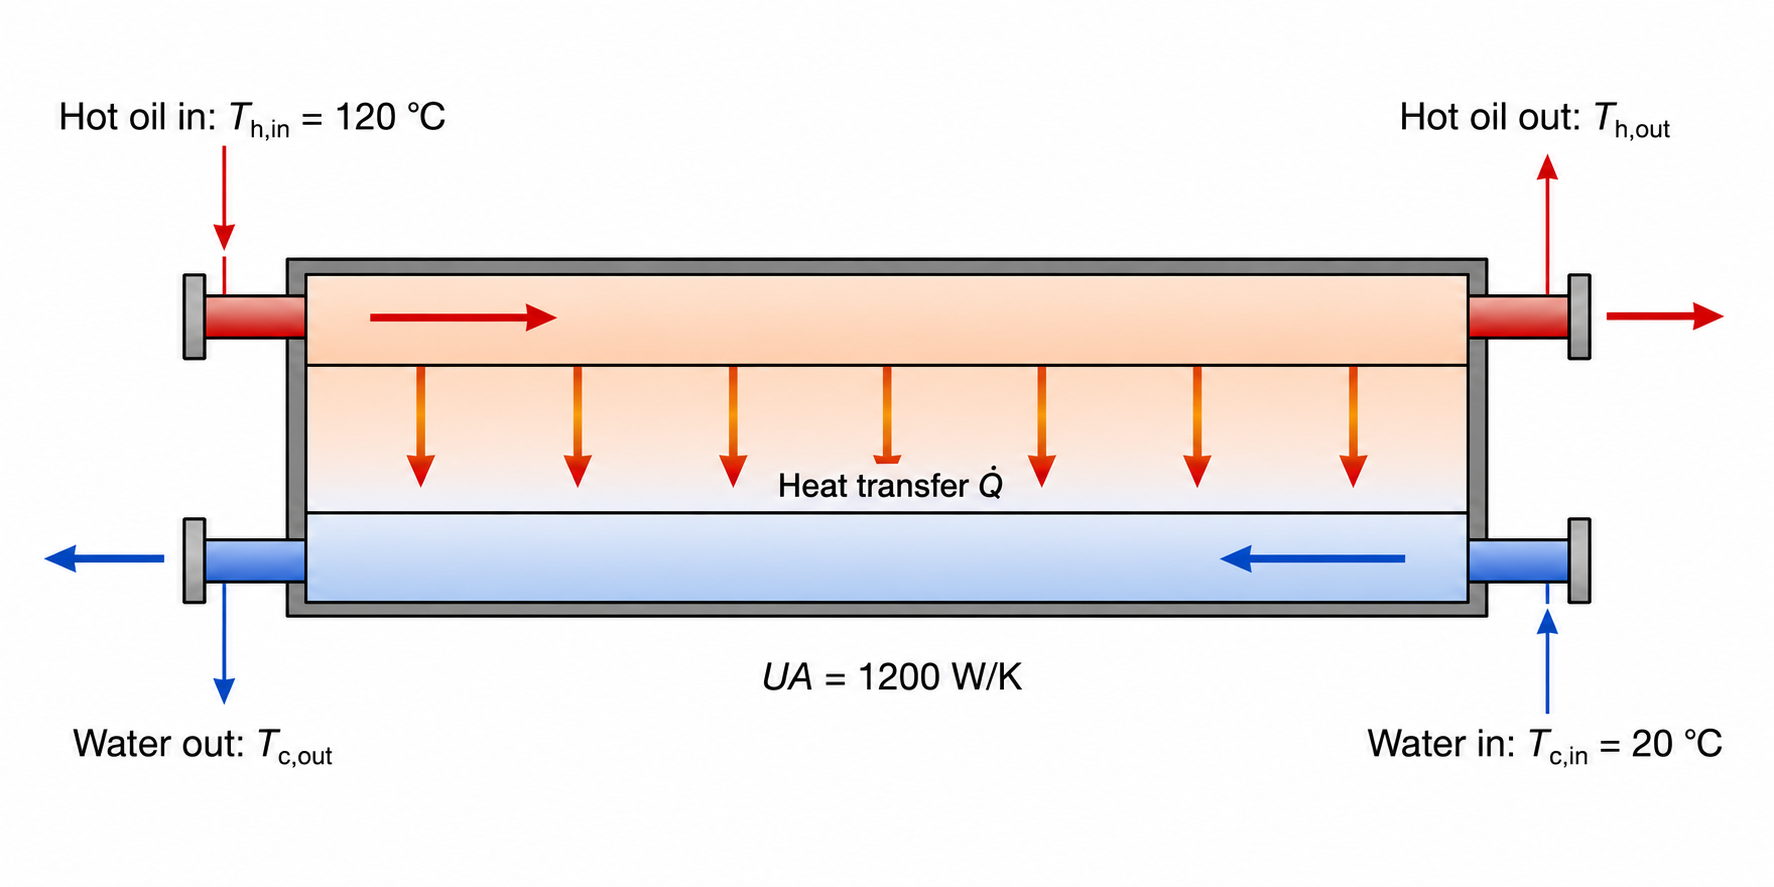

The inlet temperatures, mass flow rates, specific heat capacities, and overall thermal conductance of the heat exchanger are known. However, the outlet temperatures and the heat-transfer rate are unknown.

The goal of this problem is to determine ***(6 pts)***:

-  The outlet temperature of the water

- The outlet temperature of the oil

- The heat-transfer rate between the fluids

Explain the process and methodology, developing the energy balance, applying all the root-finding methods studied in lectures, and comparing their convergence rates and errors to assess robustness. Again, be sure to motivate and lay-out clearly all decisions you make ***(16 pts.)***

The necessary information to solve this problem is below.

## Problem variables

Use the following input values for the particular case:

The heat capacities are representative constant values for liquid water and a typical heat-transfer oil.

The subscripts have the following meanings:

- $$o$$: oil

- $$w$$: water

- $$\mathrm{in}$$: inlet

- $$\mathrm{out}$$: outlet

## Modeling assumptions

Assume that:

- The heat exchanger operates under steady-state conditions

- There is no heat loss to the surroundings

- The two fluids do not mix

- The specific heat capacities remain constant

- There is no phase change

- Kinetic- and potential-energy changes are negligible

- The overall heat-transfer coefficient is constant

- The heat exchanger operates in counter-flow

Because there is no heat loss to the surroundings, the heat lost by the oil is equal to the heat gained by the water.

## Heat-capacity rates

For each fluid, define the heat-capacity rate as


$$$$
C=\dot m c_p
$$$$


For the oil,


$$$$
{
C_o=\dot m_oc_{p,o}
}
$$$$


and for the water,


$$$$
C_w=\dot m_wc_{p,w}
}
$$$$


The units of a heat-capacity rate are


$$$$
[C]
=
\frac{\mathrm{kg}}{\mathrm{s}}
\frac{\mathrm{J}}{\mathrm{kg\,K}}
=
\frac{\mathrm{W}}{\mathrm{K}}
$$$$


The heat-capacity rate indicates the amount of heat-transfer power required to change the fluid temperature by one kelvin.

## Mathematical setup

The solution must satisfy the energy balance

$$$\dot Q=C_w(T_{w,\mathrm{out}}-T_{w,\mathrm{in}})=C_o(T_{o,\mathrm{in}}-T_{o,\mathrm{out}})$$$,

where $\dot{Q}$ is the heat-transfer rate.

For counter-flow operation, the terminal temperature differences are


$$$$\Delta T_1=T_{o,\mathrm{in}}-T_{w,\mathrm{out}}, \qquad \Delta T_2=T_{o,\mathrm{out}}-T_{w,\mathrm{in}}$$$$


The logarithmic mean temperature difference and exchanger heat-transfer equation are


$$$$\Delta T_{\mathrm{lm}}=\frac{\Delta T_1-\Delta T_2}{\ln(\Delta T_1/\Delta T_2)}, \qquad \dot Q=UA\Delta T_{\mathrm{lm}}$$$$


These equations contain the two unknowns $$T_{w,\mathrm{out}}$ \text{ and } $T_{o,\mathrm{out}}$$. To be able to determine them both, first rewrite the equations so that there exists a single equation with one unknown. Then apply a root-finding method.

# Solution problem 3

*Add your solution here using written text, equations, and blocks of code.*

%problem 3


%data input

mo = 2.0;
mw = 1.0;
cpo = 2000;
cpw = 4180;
To_in = 120;
Tw_in = 20;
UA = 1200;

% heat capacity rates

Co = mo * cpo;
Cw = mw * cpw; 

% defining Tw_out as x
% x = Tw_out
% rearranging the energy balance for To_out

To_out = @(x) To_in - (Cw/Co)*(x - Tw_in);

% LMTD

LMTD = @(x) ((To_in - x) - (To_out(x) - Tw_in)) / log((To_in - x) / (To_out(x) - Tw_in));

% objective function f(x) = 0

f = @(x) UA * LMTD(x) - Cw * (x - Tw_in);

% fixed point function

g = @(x) Tw_in + (UA/Cw) * LMTD(x);

% numerical derivative

f_prime = @(x) (f(x + 1e-4) - f(x - 1e-4)) / (2e-4);

% stopping parameters

maxit = 20;
tol = 1e-6;

% bisection method

l = 25;
u = 115;

[root_bis, rootvec_bis] = bisection_method(f, l, u, maxit);


% fixed point iteration

xk_fpi = 90;

[root_fpi, rootvec_fpi] = fixed_point_iteration(g, xk_fpi, maxit, tol);


% Newton Raphson

xk_nr = 100;
[root_nr, rootvec_nr] = newton_raphson_method(f, f_prime, xk_nr, maxit, tol);


% secant method

xk_sec = 100;
xk1_sec = 90;

[root_sec, rootvec_sec] = secant_method(f, xk_sec, xk1_sec, maxit, tol);


% comparison graph

it_bis = 0:(length(rootvec_bis)-1);
it_fpi = 0:(length(rootvec_fpi)-1);
it_nr = 0:(length(rootvec_nr)-1);
it_sec = 0:(length(rootvec_sec)-1);
err_bis = abs(rootvec_bis-root_nr)/abs(root_nr);
err_fpi = abs(rootvec_fpi-root_nr)/abs(root_nr);
err_nr = abs(rootvec_nr-root_nr)/abs(root_nr);
err_sec = abs(rootvec_sec-root_nr)/abs(root_nr);

figure;
semilogy(it_bis,err_bis,'.-');
hold on

semilogy(it_fpi,err_fpi,'.-');
semilogy(it_nr,err_nr,'*-');
semilogy(it_sec,err_sec,'.-');

xlabel('Iteration number')
ylabel('Relative error |x_k-x^*|/|x^*|')
legend('Bisection','Fixed Point','Newton Raphson','Secant')
grid on


% final results

Tw_out_final = root_nr;
To_out_final = To_out(Tw_out_final);
Q_final = Cw * (Tw_out_final - Tw_in);

fprintf('Water Outlet Temperature : %.2f deg C\n', Tw_out_final);
fprintf('Oil Outlet Temperature : %.2f deg C\n', To_out_final);
fprintf('Total Heat Transfer : %.2f kW\n', Q_final/1000);

**Best choice for problem 3:**

I found the Secant method to be the best overall method for this problem. I used a deliberately bad starting guess of 100 °C for Newton-Raphson and 100 °C and 90 °C for Secant. Newton-Raphson was faster and reached the root in only 2 iterations, while Secant needed 4. However, Secant still converged very quickly, since its order of convergence is about 1.618, the golden ratio, which is close to the quadratic convergence of Newton-Raphson (2). The main advantage is that Secant does not require the first derivative. For this LMTD equation, deriving the analytical derivative becomes quite complicated, so Secant is easier to implement while still giving fast and accurate results.